Import image and convert to gray scale,double. Record size of image.

clc;clear;
load('Contrast2.mat');
load('Contrast1.mat');
[m,n]=size(Contrast2);
origin=Contrast1;
translated=Contrast2;

Calculate myNCC

R_beforeregis=myNCC(origin(4:end,3:end),translated(4:end,3:end));
diff1=origin-translated;

In order to translate the contrast2 back. We should translate -1.8 in x and -2.1 in y.

dx=-1.8;
dy=-2.1;

Now translate in x and y direction and calculate pixel value using intepolation.(backward transformation)

% Create a grid of coordinates
[X, Y] = meshgrid(1:n, 1:m);

% Compute the translated coordinates
X_regis = X + dx;
Y_regis = Y + dy;

% Initialize the output image with NaNs
regis_image = NaN(m, n);

% Find the integer coordinates surrounding the translated coordinates
x1 = floor(X_regis);
x2 = ceil(X_regis);
y1 = floor(Y_regis);
y2 = ceil(Y_regis);

% Identify valid interpolation points (within image bounds)
validMask = x1 >= 1 & x2 <= n & y1 >= 1 & y2 <= m;

% Interpolation weights
wx = X_regis - x1;
wy = Y_regis - y1;

% Retrieve pixel values at the four surrounding points for valid points
Q11 = NaN(m, n); Q21 = NaN(m, n);
Q12 = NaN(m, n); Q22 = NaN(m, n);

Q11(validMask) = double(translated(sub2ind([m, n], y1(validMask), x1(validMask))));
Q21(validMask) = double(translated(sub2ind([m, n], y1(validMask), x2(validMask))));
Q12(validMask) = double(translated(sub2ind([m, n], y2(validMask), x1(validMask))));
Q22(validMask) = double(translated(sub2ind([m, n], y2(validMask), x2(validMask))));

% Perform bilinear interpolation for valid points
regis_image(validMask) = (1 - wx(validMask)) .* (1 - wy(validMask)) .* Q11(validMask) + ...
                         wx(validMask) .* (1 - wy(validMask)) .* Q21(validMask) + ...
                         (1 - wx(validMask)) .* wy(validMask) .* Q12(validMask) + ...
                         wx(validMask) .* wy(validMask) .* Q22(validMask);
regis_image(isnan(regis_image)) = 0;

Calculate myNCC and subtract image with Contrast1

Difference=origin-regis_image;
% regis_image=uint8(regis_image);
% origin=uint8(origin);
% translated=uint8(translated);
R_afterregistration=myNCC(origin(4:end,3:end),regis_image(4:end,3:end));

 Print the result value and show the difference image with scale bar

fprintf('The result before registration is %d and after registration is %d.\n',R_beforeregis,R_afterregistration);

The result before registration is 9.778922e-01 and after registration is 9.998184e-01.


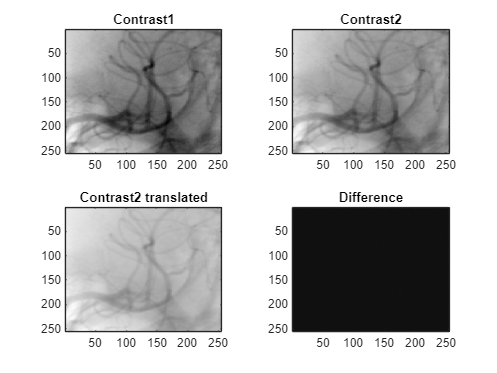


tiledlayout(2,2)
nexttile
imagesc(origin)
colormap('gray')
title('Contrast1')

nexttile
imagesc(translated)
title('Contrast2')
colormap('gray')
nexttile
imagesc(regis_image)
title('Contrast2 translated')
colormap('gray')
nexttile
imagesc(Difference)
title('Difference')
colormap('gray')

Q3


%calling the cost function SSE
costF= @(t) SSE(origin, translated, t(1),t(2) );
% cost_test= SSE(origin, translated, -1.8, -2.1);
% display(cost_test)

%initialize first guess for translation, [tx, ty]
t_i= [0,0];
%initialize array to store frames
frames=[];

%run fminsearch on optimal translation parameters
% and custom options to show iterations
options= optimset("Display",'iter','MaxIter', 70,'TolX',1e-6, 'TolFun',1e-6);
[t_optimal, fval]= fminsearch(costF, t_i, options);

 
 Iteration   Func-count         f(x)         Procedure
     0            1      9.17369e+06         
     1            3      9.17256e+06         initial simplex
     2            5       9.1706e+06         expand
     3            7      9.16926e+06         expand
     4            9      9.16474e+06         expand
     5           11      9.16006e+06         expand
     6           13      9.14934e+06         expand
     7           15      9.13666e+06         expand
     8           17      9.11438e+06         expand
     9           19       9.0941e+06         expand
    10           21      9.08424e+06         expand
    11           23      9.08424e+06         contract outside
    12           25      9.08424e+06         contract inside
    13           27      9.08283e+06         reflect
    14           29      9.08153e+06         reflect
    15           31      9.08124e+06         reflect
    16           33      9.07908e+06         reflect
    17           34      9.07908e

fprintf(['The optimal translation parameters t_x is %.4f, t_y is %4f, ' ...
    'and minimal cost function is %d\n'], ...
    t_optimal(1), t_optimal(2), fval);

The optimal translation parameters t_x is 0.0192, t_y is 0.030835, and minimal cost function is 9.067346e+06


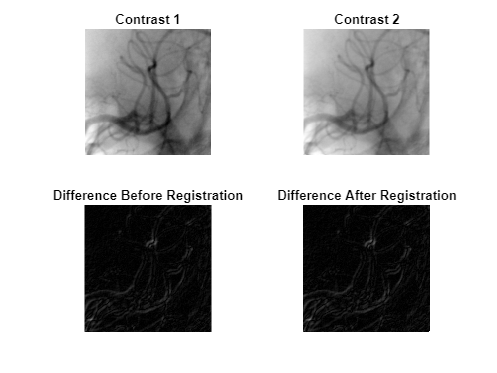


%extract the optimal tx and ty
tx_optimal=t_optimal(1);
ty_optimal= t_optimal(2);
%registered new image with optimal translation, default bilinear method
Im_optimal= imtranslate(translated, [tx_optimal,ty_optimal],'OutputView','same');

%difference images before and after optimization
diffBefore= imabsdiff(origin, translated);
diffAfter= imabsdiff(origin, Im_optimal);

%display orignal images and difference image in grayscale
figure;
subplot(2,2,1), imshow(origin,[]), title('Contrast 1');
subplot(2,2,2), imshow(translated,[]), title('Contrast 2');
subplot(2,2,3), imshow(diffBefore,[]), title('Difference Before Registration');
subplot(2,2,4), imshow(diffAfter,[]), title('Difference After Registration');

% below section is to try to capture frames into a movie

%play the movie 
figure;
movie(frames,1,5) % frame rate of 5 frames per second
%export the movie
% create an object and then write video files to it
videoFrame= VideoWriter('Translated Images Movie.avi');
open(videoFrame);
writeVideo(videoFrame, frames);
close(videoFrame);
disp('Movie exported successfully');

